# ODE Lab: Creating your own ODE solver in MATLAB

## Creating new functions using m-files

## Exercise 1

Objective: Write your own ODE solver (using the Heun/Improved Euler Method).

Details: This m-file should be a function which accepts as variables (t0,tN,y0,h), where t0 and tN are the start and end points of the interval on which to solve the ODE, y0 is the initial condition of the ODE, and h is the stepsize. You may also want to pass the function into the ODE the way `ode45` does (check lab 2).

Note: you will need to use a loop to do this exercise. You will also need to recall the Heun/Improved Euler algorithm learned in lectures. 

%done in separate m-file (IEM.m)

## Exercise 2

Objective: Compare Heun with `ode45`.

Specifics: For the following initial-value problems (from lab 2, exercises 1, 4-6), approximate the solutions with your function from exercise 1 (Improved Euler Method). Plot the graphs of your Improved Euler Approximation with the `ode45` approximation.

(a) `y' = y tan t + sin t, y(0) = -1/2` from `t = 0` to `t = pi`

(b) `y' = 1 / y^2 , y(1) = 1` from `t=1` to `t=10`

(c) `y' = 1 - t y / 2, y(0) = -1` from `t=0` to `t=10`

(d) `y' = y^3 - t^2, y(0) = 1` from `t=0` to `t=1`

Comment on any major differences, or the lack thereof. You do not need to reproduce all the code here. Simply make note of any differences for each of the four IVPs.

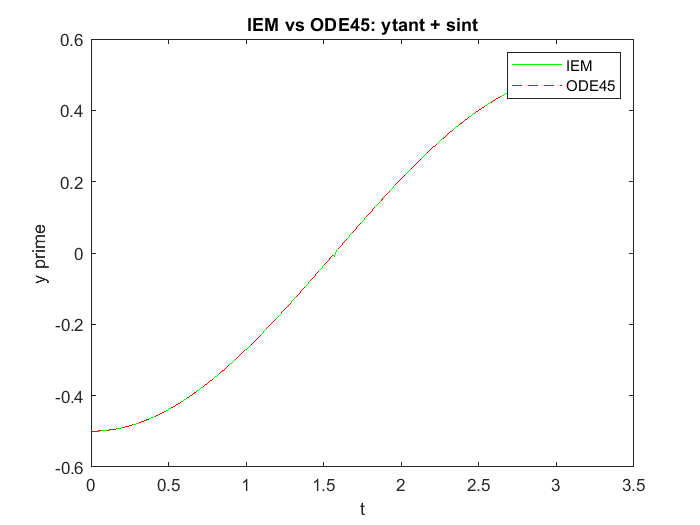

%(a)
clear all;
fa = @(t,y) (y.*tan(t)) + sin(t); %inline function definition

[tA,yA] = IEM(0,pi,-0.5,0.01,fa); %using IEM function IEM(t0,tN,y0,h) 

plot(tA,yA,'g') % plot  IEM solved 

hold on;
[tA,solna] = ode45(fa,[0,pi],-0.5);
plot(tA,solna,'r--')

title('IEM vs ODE45: ytant + sint');
xlabel('t');
ylabel('y prime');
legend('IEM', 'ODE45');
hold off;

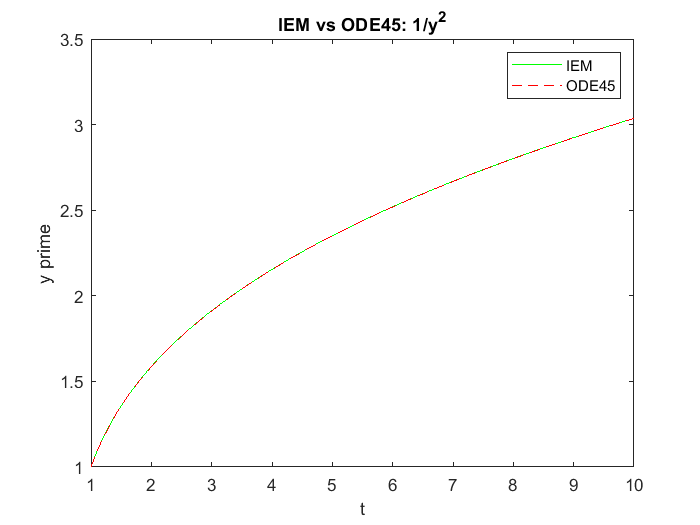

% No observable differences between using IEM and ode45

%(b)
fb = @(t,y) 1/y^2;
[tb,yb] = IEM(1,10,1,0.01,fb);
plot(tb,yb,'g')

hold on;
[tb,solnb] = ode45(fb,[1,10],1);
plot(tb,solnb,'r--')

title('IEM vs ODE45: 1/y^2');
xlabel('t');
ylabel('y prime');
legend('IEM', 'ODE45');
hold off;

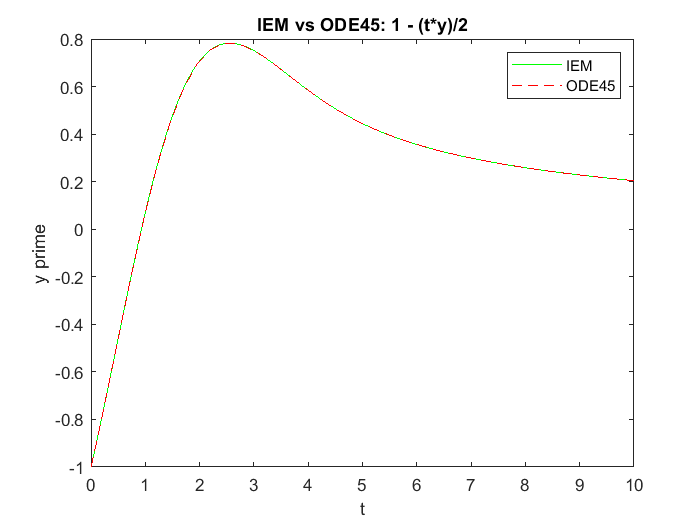

% No observable differences between using IEM and ode45

%(c)
fc = @(t,y) 1 - (t*y)/2;
[tc,yc] = IEM(0,10,-1,0.01,fc);
plot(tc,yc,'g')
hold on;
[tc,solnc] = ode45(fc,[0,10],-1);
plot(tc,solnc,'r--')

title('IEM vs ODE45: 1 - (t*y)/2');
xlabel('t');
ylabel('y prime');
legend('IEM', 'ODE45');
hold off;

% No observable differences between using IEM and ode45

%(d)
fd = @(t,y) y^3 - t^2;
[td,yd] = IEM(0,1,1,0.01,fd);
plot(td,yd,'g')

hold on;
[td,solnd] = ode45(fd,[0,1],1);

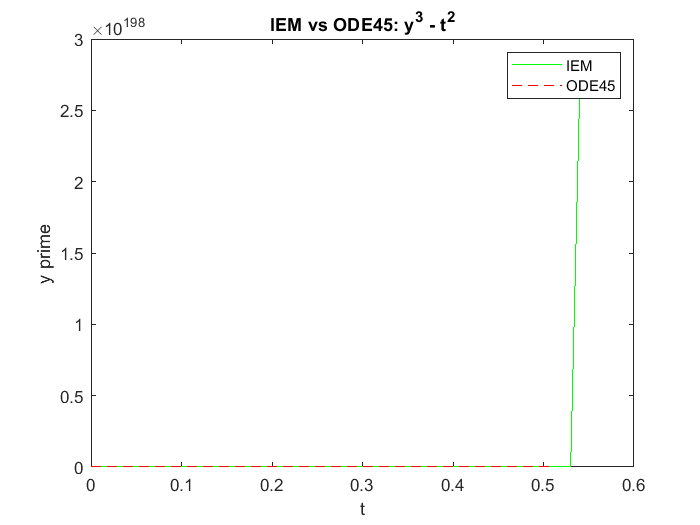

plot(td,solnd,'r--')


title('IEM vs ODE45: y^3 - t^2');
xlabel('t');
ylabel('y prime');
legend('IEM', 'ODE45');
hold off;

% IEM solver's plot goes to positive infinity at around t = 0.5 
% while ode45 stops plotting at about t=0.5

% This is because if a solution stops to exist (i.e. goes to infinity) at a
% point, MATLAB automatically stops the slope graph

## Exercise 3

Objective: Use Euler's method and verify an estimate for the global error.

Details: 

(a) Use Euler's method (you can use euler.m from iode) to solve the IVP

`y' = 2 t sqrt( 1 - y^2 ) , y(0) = 0`

from `t=0` to `t=0.5`.

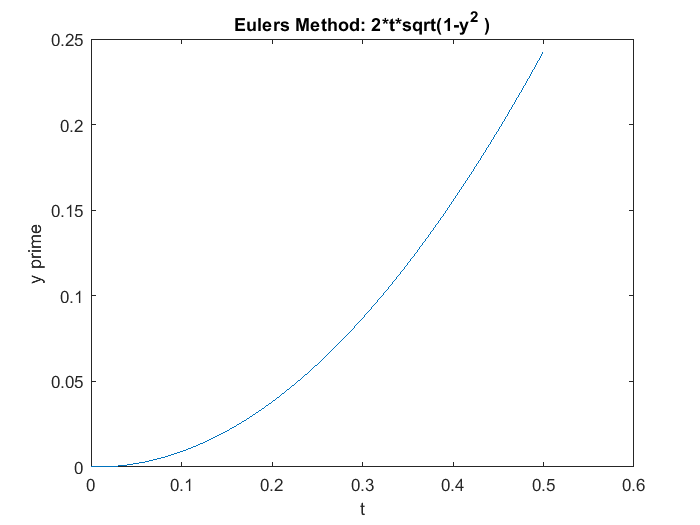

clear all;
syms t y

f = @(t,y) 2*t*sqrt(1-y^2 );
[t,yeuler] = euler(0,0.5,0,0.01,f); % using euler.m
plot(t,yeuler);
title('Eulers Method: 2*t*sqrt(1-y^2 )');
xlabel('t');
ylabel('y prime');


fprintf ('The value of y at t = 0.5 using euler.m is %f\n', yeuler(end));

The value of y at t = 0.5 using euler.m is 0.242672


(b) Calculate the solution of the IVP and evaluate it at `t=0.5`.

% General Solution: y = sin(t^2+C)
% Particular Solution to IVP: Given y(0) = 0
% C = 0, pi

% For C = 0, y = sin(0.25)
% For C = pi, y = sin(0.25 + pi)

yt= sin(0.5^2) %Evaluated at t=0.5

yt = 0.2474

(c) Read the attached derivation of an estimate of the global error for Euler's method. Type out the resulting bound for En here in a comment. Define each variable.

% there exists an M that is greater than the absolute value of f and both partial
% derivatives (in terms of t and y)
f = @(t,y) 2*t*sqrt(1-y^2);
dft = @(t,y) 2*(1 - y^2)^(1/2); %partial derivative of f wrt t
dfy = @(t,y) -(2*t*y)/(1 - y^2)^(1/2); %partial derivative of f wrt y

%The absolute values of the above 3 are all increasing 
%M can be found by subbing in t = 0.5 to the above 3 functions and using
%the largest absolute value
%Here M = 1 which is the maximum out of abs(f), abs(dfy), abs(dft)

M = 1; %set M 
h = 0.01; %step size (the delta t)
n = 51; %number of steps (t1-t0)/h =0.5/0.01 = 51

% Approximate Error
Eapprox = (((1+M)*h)/2)*(exp(M*h*n)-1)

Eapprox = 0.0067

(d) Compute the error estimate for `t=0.5` and compare with the actual error.

% Actual Error
Eactual = abs(yeuler(end) - yt)

Eactual = 0.0047

% The approximate error is larger than the actual error 
% since approximate error uses upper bounds
% to calculate, making it higher than the actual 

(e) Change the time step and compare the new error estimate with the actual error. Comment on how it confirms the order of Euler's method.

fprintf('Stepsize |  Eapprox  | Eactual\n');

Stepsize |  Eapprox  | Eactual



for i = (1:5)%for 5 different time steps
    h = 0.1^i; %changing step size 
    n = 0.5/h;
    
    Eapprox = (((1+M)*h)/2)*(exp(M*h*n)-1);
    f = @(t,y) 2*t*sqrt(1-y^2 );
    [t,yeuler] = euler(0,0.5,0,h,f); %now with a varying h
    Eactual = abs(yeuler(end) - yt);
    fprintf('%f | %f | %f\n',h, Eapprox, Eactual); 
    fprintf('\n');
end

0.100000 | 0.064872 | 0.048097


0.010000 | 0.006487 | 0.014262


0.001000 | 0.000649 | 0.001440


0.000100 | 0.000065 | 0.000144


0.000010 | 0.000006 | 0.000014


## Adaptive Step Size

## Exercise 4

Objective: Create an Adaptive Euler method, with an adaptive step size `h`.

Details: Create an m-file which accepts the variables `(t0,tN,y0,h)`, as in exercise 1, where `h` is an initial step size. You may also want to pass the function into the ODE the way `ode45` does.

Create an implementation of Euler's method by modifying your solution to exercise 1. Change it to include the following:

(a) On each timestep, make two estimates of the value of the solution at the end of the timestep: `Y` from one Euler step of size `h` and `Z` from two successive Euler steps of size `h/2`. The difference in these two values is an estimate for the error.

(b) Let `tol=1e-8` and `D=Z-Y`. If `abs(D)<tol`, declare the step to be successful and set the new solution value to be `Z+D`. This value has local error `O(h^3)`. If `abs(D)>=tol`, reject this step and repeat it with a new step size, from (c).

(c) Update the step size as `h = 0.9*h*min(max(tol/abs(D),0.3),2)`.

Comment on what the formula for updating the step size is attempting to achieve.

% Adaptive Euler written on separate m file (Aeuler.m)

% When the derivative of the solution changes rapidly, the step size h is changed to a smaller number
% to minimize this jump. 
% The adaptive step size controls the errors 
% to make sure they remain inside the error bounds. 

% The errors are inside the bounds when the difference (D) 
% between the evaluated Y from full step and Y from  half steps is smaller than the tolerance

%In other words, this is a test to determine is an adaptive step size is needed 
%In this case, the normal stepping is fine. Otherwise, the new step size is
%needed

%To update h to the new h:
% Calculate tolerance (1e-8) divided by D (difference between Y(h) and Z(h/2) ) 
% and compare it to 0.3

% Take the max of the two
% Compare the max of the two with 2
% Take the min of the two  


## Exercise 5

Objective: Compare Euler to your Adaptive Euler method.

Details: Consider the IVP from exercise 3.

(a) Use Euler method to approximate the solution from `t=0` to `t=0.75` with `h=0.025`.

(b) Use your Adaptive Euler method to approximate the solution from `t=0` to `t=0.75` with initial `h=0.025`.

(c) Plot both approximations together with the exact solution.

clear all;
f = @(t,y) 2*t*sqrt(1-y^2);
[t,yeuler] = euler(0,0.75,0,0.025,f); %Euler's 
[tA,yA] = Aeuler(0,0.75,0,0.025,f); %Adaptic Euler's 
yt= sin(0.5^2) %Evaluated at t=0.5

yt = 0.2474

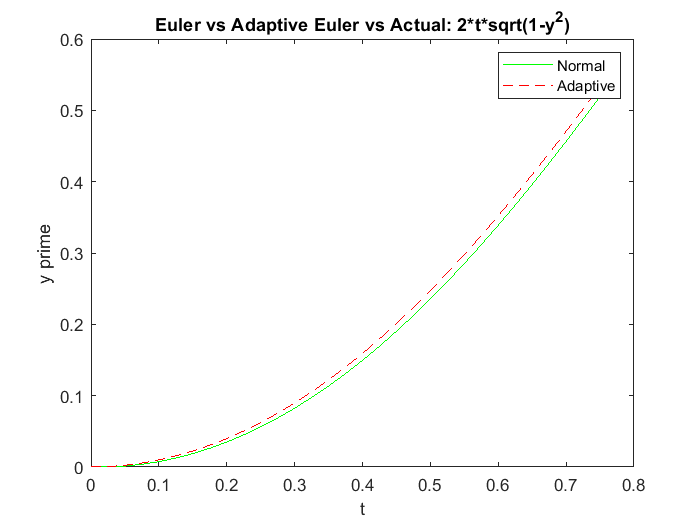


plot(t,yeuler,'g');
hold on;

plot(tA,yA,'r--');
hold on;

legend('Normal','Adaptive');
title('Euler vs Adaptive Euler vs Actual: 2*t*sqrt(1-y^2)');



xlabel('t');
ylabel('y prime');
hold off;

## Exercise 6

Objective: Problems with Numerical Methods.

Details: Consider the IVP from exercise 3 (and 5).

(a) From the two approximations calculated in exercise 5, which one is closer to the actual solution (done in 3.b)? Explain why.

% Adaptive Euler should be closer to the actual solution since step sizes
% are made smaller when changes in slope are large. 

%This insures that the actual function is never too far from the real
%solution because there is a limit on the error bounds. 


(b) Plot the exact solution (from exercise 3.b), the Euler's approximation (from exercise 3.a) and the adaptive Euler's approximation (from exercise 5) from `t=0` to `t=1.5`.

clear all;
tt=0:0.025:1.5;
f = @(t,y) 2*t*sqrt(1-y^2);
[t,yeuler] = euler(0,1.5,0,0.025,f);
[tA,yA] = Aeuler(0,1.5,0,0.025,f);
yt = sin(tt.^2);

% Plotting
plot(t,yeuler,'g');

hold on;


plot(tA,yA,'r--');

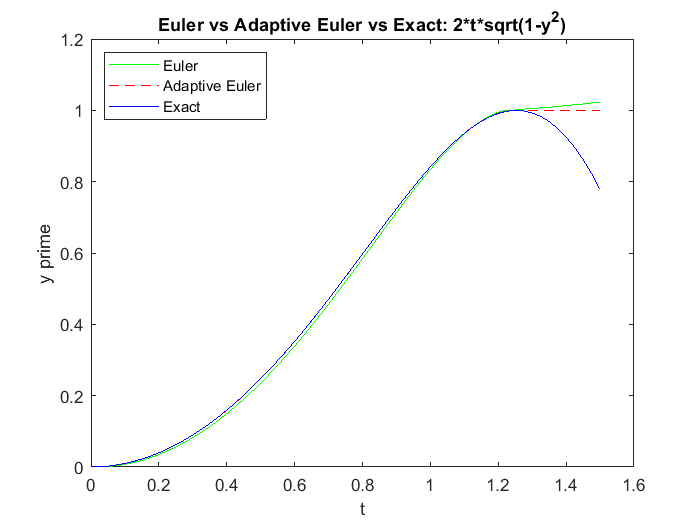

hold on;


plot(tt,yt,'b');

legend('Euler', 'Adaptive Euler ','Exact','Location','northwest');
title('Euler vs Adaptive Euler vs Exact: 2*t*sqrt(1-y^2)');
xlabel('t');
ylabel('y prime');

(c) Notice how the exact solution and the approximations become very different. Why is that? Write your answer as a comment.

% Adaptive Euler's method can deal 
% with inflection points (where the slope of the derivative changes rapidly), 
% which Euler's cannot. There are inflection points in the derivative of
% the sin graph which is the function solution in this case. The solutions
% become very different because at pi/2, it is the point on the graph where
% the slope stops changing 